# EE525 Project 4

Author: Grant Gallagher

Date: 11/20/2021

Use MATLAB to implement a Kalman filter that tracks a moving target. The dataset is 2D (X,Y) measurement data of the position of a US Navy ship over a span of approximately eight minutes. Set up a Kalman filter with  a  [position_X,  velocity_X,  position_Y,  velocity_Y]  state.  The Kalman filter should function in ‘realtime’ – that is processing should occur as the measurements are read. Experiment with the filter parameters, and study their effects on tracking performance. 

Submit the following:

-  A report documenting the set up and implementation of the filter, plots  of  the  raw  measurements  and  filtered  signal,  the  problems you  encountered,  analysis  and  discussion  of  the  results.  Also include your effort in “tweaking” the filter parameters (55 points).

- Well-documented  source  code.  If  more  than  one  function/file  is  used, provide detailed description as to how to run it (25 points). 

- Repeat 1-2 for an additional dataset. It is a 3D (X,Y,Z) measurement data of the position of a US Navy submarine over a span of approximately two minutes (20 points).  

Clear Console

clc
clear

Import the Data

varNames = {'Time','North','East'};
stateVarNames = {'Time','X_North','V_North','X_East','V_East'};
varTypes = {'datetime','double','double',};
[rawData, rawDataTable]= readShipData('2Ddata.txt',varNames,varTypes)

rawData = 	1.0e+04 *

    0.0001    5.8259    8.7671
    0.0002    5.8261    8.7673
    0.0003    5.8264    8.7674
    0.0004    5.8265    8.7674
    0.0005    5.8265    8.7674
    0.0006    5.8267    8.7675
    0.0007    5.8269    8.7674
    0.0008    5.8270    8.7674
    0.0009    5.8272    8.7674
    0.0010    5.8273    8.7674


rawDataTable = 458×3 table
     Time     North    East 
    ______    _____    _____

         1    58259    87671
         2    58261    87673
         3    58264    87674
         4    58265    87674
         5    58265    87674
         6    58267    87675
         7    58269    87674
         8    58270    87674
         9    58272    87674
        10    58273    87674
        11    58274    87675
        12    58276    87675
        13    58276    87675
        14    58277    87676
        15    58279    87676
    15.999    58280    87676


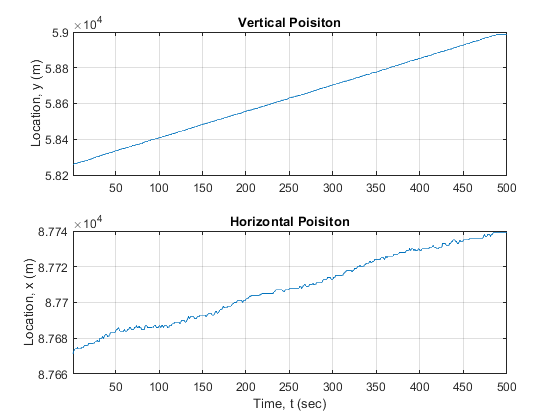


fig1 = figure(1);
subplot(2,1,1);
plot(rawDataTable.Time,rawDataTable.North)
title('Vertical Poisiton')
ylabel('Location, y (m)')
grid on
xlim([min(rawDataTable.Time) max(rawDataTable.Time)])

subplot(2,1,2);
plot(rawDataTable.Time,rawDataTable.East)
title('Horizontal Poisiton')
ylabel('Location, x (m)')
xlabel('Time, t (sec)');
grid on
xlim([min(rawDataTable.Time) max(rawDataTable.Time)])

Define State Space Matrix


$$x=x_0 +\dot{x} \Delta t+\frac{1}{2}\ddot{x} {\Delta t}^2$$



$$x^+ =x^- +\Delta t{\dot{x} }^- +\frac{1}{2}{\Delta t}^2 {\ddot{x} }$$



$${\dot{x} }^+ ={\dot{x} }^- +{\Delta t\ddot{x} }^-$$



$$\left\lbrack \begin{array}{c}
x\\
\dot{x} \\
y\\
\dot{y} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
1 & \Delta t & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & \Delta t\\
0 & 0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
\dot{x} \\
y\\
\dot{y} 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
\frac{1}{2}\Delta t^2 \\
\Delta t\\
\frac{1}{2}\Delta t^2 \\
\Delta t
\end{array}\right\rbrack u$$


Declare Matrices

dt = 1;
F = [1 dt 0  0;
     0  1 0  0;
     0  0 1 dt;
     0  0 0  1];
n = length(F); % Order of the system
G = [0 0 0 0]';
B = eye(n);
H = eye(n);

[phi, Q] = vanLoan(F,G,1,dt)

phi =     2.7183    2.7183         0         0
         0    2.7183         0         0
         0         0    2.7183    2.7183
         0         0         0    2.7183


Q =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


R = eye(n);

Initial Estimates for ${{\hat{x} }_k }^-$ and its error covariance ${P_k }^-$.

X = zeros(size(rawData)+[0 n/2])

X =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0



x_hat_prev = [58000;
              2;
              87000;
              2]

x_hat_prev =        58000
           2
       87000
           2



P_prev = eye(n)

P_prev =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


Predicted Values

for k = 1:20
    %% --- Measurement Update ("Correct") ---
    % (1) Compute Kalman gain
    K = P_prev*H'*inv(H*P_prev*H'+R);
    
    % (2) Update estimate with measurement z_k
    x = [rawData(k,2);
         0;
         rawData(k,3);
         0];
     
    z = H*x;
    
    
    x_hat = x_hat_prev+K*(z-H*x_hat_prev);
    
    % (3) Update the error covariance
    P = (eye(n)-K*H)*P_prev;
    
    
    %% --- Time update ("Predict") ---
    % (1) Project the state ahead
    x_hat_new = phi*x_hat;
    
    X(k,2:end) = x_hat_new';
    x_hat_prev = x_hat_new;
    % (2) Project the error covariance ahead
    P_new = phi*P*phi'+Q;
    P_prev = P_new;
end
X

X = 	1.0e+05 *

         0    1.5802    0.0000    2.3741    0.0000
         0    1.6891   -0.3893    2.5414   -0.5843
         0    1.4017   -0.6891    2.1099   -1.0357
         0    1.2880   -0.7773    1.9386   -1.1690
         0    1.2611   -0.7907    1.8979   -1.1895
         0    1.2586   -0.7881    1.8940   -1.1858
         0    1.2605   -0.7846    1.8967   -1.1806
         0    1.2622   -0.7825    1.8991   -1.1774
         0    1.2632   -0.7814    1.9005   -1.1757
         0    1.2637   -0.7809    1.9012   -1.1750


% fig2 = figure(2);
% hold on
% plot(X.Time, X.East);
% plot(data.Time,data.East)
% hold off

Measured Values

Calculate Expected Values

## Import Data

function [dataArray, dataTable] = readShipData(fileName,varNames,varTypes)
    delimiter = '\t';        % Horizontal tab delimiter
    dataStartLine = 8;       % Start on 8th line
    extraColRule = 'ignore'; % Ignore extra columns
    
   
    opts = delimitedTextImportOptions('VariableNames',varNames,...
                                    'VariableTypes',varTypes,...
                                    'Delimiter',delimiter,...
                                    'DataLines', dataStartLine,...
                                    'ExtraColumnsRule',extraColRule);
    opts = setvaropts(opts,'Time','InputFormat','HH:mm:ss.SSS'); % Set datetime format
    dataTable = readtable(fileName, opts); % Return the ship data as a table
    dataTable = rmmissing(dataTable,1);
    
    dataTable.Time = datenum(dataTable.Time);
    dataTable.Time = (dataTable.Time - dataTable.Time(1)) * 60 * 60 * 24 + 1;
    
    dataArray = table2array(dataTable);
    
end

## Van Loan Method

function [phi, Q] = vanLoan(F,G,W,dt)
    % Calculate the size of the system
    n = length(F);
    
    % Determine A and B matrices
    A = [ -F       G*W*G';
          zeros(n)     F']*dt;
    B = expm(A);
    
    % Calculate phi and Q
    phi = B(n+1:end,n+1:end)';
    Q = phi*B(1:n,n+1:end);
end